# Deber: Semana #1

## Ejercicio 1

Identificar si las siguientes los siguientes son nombres válidos de variables.

- _altura

- altura_

- 2paises

- Musica_Favorita

- Numero-de-pacientes

### Solución

isvarname _altura

ans = logical
   0

isvarname altura_

ans = logical
   1

isvarname 2paises

ans = logical
   0

isvarname Musica_Favorita

ans = logical
   1

isvarname Numero-de-pacientes

ans = logical
   0

## Ejercicio 2

Realizar las siguientes operaciones:

- 
$$\pi^{e+1}$$


- 
$$\sqrt{\sqrt[3\ldotp 71]{\frac{e^{\pi } }{2}}}$$


- $\frac{\sqrt{5a+3b^{2a} }}{\sqrt[a]{3\ldotp 1b}}$, donde $a=\pi$ y $b=0\ldotp 5$.

### Solución

%1ro
pi^(exp(1) + 1)

ans = 70.5575

%2do
((exp(pi)/2)^(1/3.71))^(1/2)

ans = 1.3909

%3ro
a = pi;
b = 0.5; 
((5*a + 3*(b^2*a))^(1/2))/(3.1*b)^(1/a)

ans = 3.6968

## Ejercicio 3

El área de un círculo se encuentra mediante la expresión $A=\pi r^2$. Considerando lo anterior:

- Determinar el radio que tiene un círculo de área $2\pi \;{\mathrm{u}}^2$. $r\;=\sqrt{\frac{A}{\pi }}\;$

- ¿Cuál es la diferencia entre el anterior radio y el radio de un círculo de área $5\ldotp 2\pi \;{\mathrm{u}}^2$?

- ¿Cuál debe ser el radio para que el área sea $\pi \times {10}^2 \;{\mathrm{u}}^2$?

Luego, el volumen de un cilindro se determina mediante el área de la base y la altura, $V=A_{\textrm{base}} \times h=\pi r^2 h$, entonces:

- ¿Cuál debe ser el área para que el volumen de un cilindro sea de $10{\;\mathrm{u}}^3$ con una altura de $2\ldotp 5\;\mathrm{u}$? $A=\frac{V}{h}$

- ¿Cuáles serán las alturas para volúmenes desde $1\;{\mathrm{u}}^3$ hasta $1000\;{\mathrm{u}}^3$ con un diámetro de $10\;\mathrm{u}$? $h=\frac{V}{A}$

- Utilizando las alturas anteriores, ¿cuál debe ser el área para que el volumen sea $500\;{\mathrm{u}}^3$ en todos los casos?

### Solución

% Ítem 1
A = 2*pi;
r = (A/pi)^(1/2);
fprintf("El radio del círculo de área %.3f es de: %.3f ", A, r)

El radio del círculo de área 6.283 es de: 1.414 

% Ítem 2 D=r2-r
A2 = 5.2*pi;
r2 = (A2/pi)^(1/2);
D = r2 - r;
fprintf("Radio del círculo de área %.2f ; Círculo de área %.2f es: %.2f ",A,A2,D);

Radio del círculo de área 6.28 ; Círculo de área 16.34 es: 0.87 

% Ítem 3 r3
A3 = pi*100;
r3 = (A3/pi)^(1/2);
fprintf("El radio del círculo de área %.2f es de: %.0f ", A3, r3);

El radio del círculo de área 314.16 es de: 10 

% Volumen: Ítem 1 h=V/A
clear
V = 10;
h = 2.5; 
A = V/h;
fprintf("El area de la base de un cilindro es de: %i",A);

El area de la base de un cilindro es de: 4

% Ítem 2 h=V/A
clear
V = [0:100:1000];
A = 10;
h = V/A

h =      0    10    20    30    40    50    60    70    80    90   100


V2 = [500 500 500 500 500 500 500 500 500 500 500]

V2 =    500   500   500   500   500   500   500   500   500   500   500



    for c = 1:1:11
        
    end
    
  % fin del cálculo (revisar)


## Ejercicio 4

Las poblaciones tienden a expandirse exponencialmente. Esto se puede modelar mediante la ecuación diferencial:


$$\frac{\mathrm{d}}{\mathrm{d}t}P=\textrm{kP}$$


donde

        $P=$ población actual

        $k=$ tasa de crecimiento (se expresa en términos de la unidad)

        $t=$ tiempo

Si inicialmente se tienen 500 personas que se reproducen a una tasa de crecimiento constante de 65% por año, determinar cuántas personas habrán dentro de 4 años.

Desplegar una conclusión adecuada utilizando la función de despliegue formateado.

### Solución

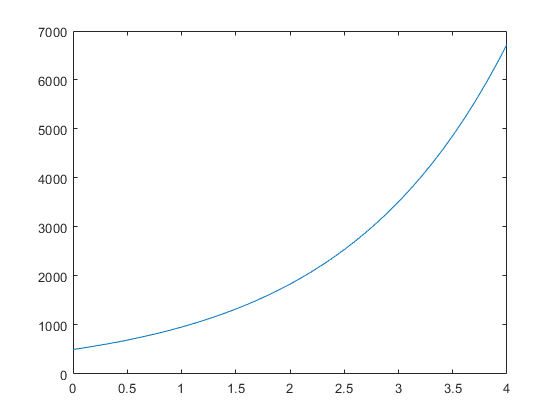

%Gráfica 1
  clear
tRange = [0 4];
P0 = 500;

[tSol, PSol] = ode45(@modeloPoblacional, tRange, P0);
plot(tSol, PSol)

format bank
P4 = PSol(end)

P4 =        6731.87


%Salida final ejercicio 4
format short
fprintf("Con una población inicial de %i personas, con una tasa de crecimiento de %.2f\n" + ...
    "y dentro de %i años se tendrá una población de %.0f personas.\n", ...
    P0, 0.65, 4, P4);

Con una población inicial de 500 personas, con una tasa de crecimiento de 0.65
y dentro de 4 años se tendrá una población de 6732 personas.


## Ejercicio 5

La ley del enfriamiento de Newton establece que la tasa de pérdida de calor de un cuerpo es proporcional a la diferencia de temperatura entre el cuerpo y sus alrededores. Esta se modela mediante la siguiente ecuación diferencial:


$$\frac{\mathrm{d}}{\mathrm{d}t}T=c\left(T-T_A \right)$$


donde

        $T=$ temperatura actual (en Kelvin)

        $T_A =$ temperatura ambiente (en Kelvin)

        $c=$ constante de proporcionalidad

         $t=$ tiempo (en segundos)

Si la temperatura de un pastel recién sacado del horno es $180\;\textrm{°}C$ y la temperatura ambiente es de $23\ldotp 5\;\textrm{°}C$, ¿cuál será la temperatura dentro de 2 horas?

Desplegar una conclusión adecuada utilizando la función de despliegue formateado.

### Solución

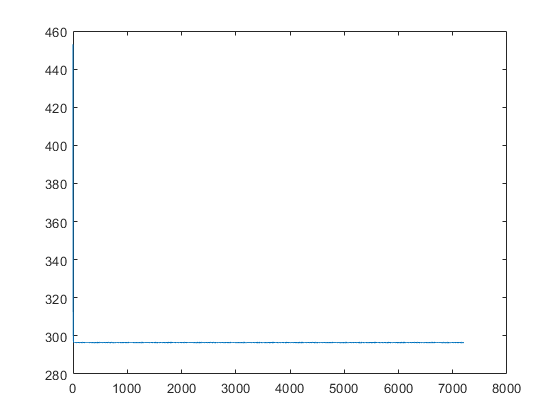

%Gráfico
clear
tRang = [0 7200];
T0 = 273+180;

[tSol1, PSol1] = ode45(@leyEnfriamiento, tRang, T0);
plot(tSol1, PSol1)

%Mandamos a graficar
format bank
P2 = PSol1(end)

P2 =         296.58


%Salida
format short
fprintf("Con una temoeratura inicial de %iº C, con una constante de proporcionalidad de %.4f\n" + ...
    "y dentro de %i horas se tendrá una temperatura de %.2fº C.\n", ...
    T0-273, -(273+23.5)/(273+180), 2, P2-273);

Con una temoeratura inicial de 180º C, con una constante de proporcionalidad de -0.6545
y dentro de 2 horas se tendrá una temperatura de 23.58º C.


function dTdt = leyEnfriamiento(~, T)
    c = -(273+23.5)/(273+180);
    Ta = 296.5;
    dTdt = c.*(T-Ta);
end

function dPdt = modeloPoblacional(~, P)
    k = 0.65;
    dPdt = k.*P;
end
%(Nota: Revisar valores para k tercer literal)